clear
syms xx x1 x2 x3 x4 x5 y1 y2 y3 y4 y5
x1=0;
x2=100;
x3=500;
x4=700;
x5=3000;
y3p=100;% процент между ровным распределением и максимально возможным пиком.
%step=0.1;
XD=(x1:1:x5);
R(1)=(x3-x1)/(x5-x1);
R(2)=(x5-x3)/(x5-x1);%соотношение каждой "половинки" графика
y2=(y3-y1)/4+y1;
y4=(y3-y5)/4+y5;
%исключение точек разрыва
K=(y2 + x2*y1 + x1*y3 + x2*y3 + x3*y2 + sqrt(-(y2 - y3)*(x2 - 1)^3*(y2 - y3 + x2*y1 - 2*x2*y2 - x3*y1 + x2*y3 + x3*y2)) + 2*x1*x2*y2 + x1*x3*y1 == y3 + x1*y2 + 2*x2*y2 + x3*y1 + x1*x2*y1 + x1*x2*y3 + x1*x3*y2&y2 + x2*y1 + x2*y3 + x3*y2 ~= y3 + 2*x2*y2 + x3*y1)|(y4 + x3*y4 + x4*y3 + x5*y3 + x4*y5 + sqrt((y3 - y4)*(x4 - 1)^3*(y4 - y3 + x3*y4 + x4*y3 - x3*y5 - 2*x4*y4 + x4*y5)) + x3*x5*y5 + 2*x4*x5*y4 == y3 + x3*y5 + 2*x4*y4 + x5*y4 + x3*x5*y4 + x4*x5*y3 + x4*x5*y5&y3 + x3*y5 + 2*x4*y4 ~= y4 + x3*y4 + x4*y3 + x4*y5)|(x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2&x1^2*x2 + 2*x1 + 3*x2^2 ~= x1^2 + 2*x1*x2 + x2^3 + 2*x2)|(x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5&x4^3 + 2*x4*x5 + 2*x4 + x5^2 ~= 3*x4^2 + x4*x5^2 + 2*x5)|(x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2&x2 + x3 + 4*x1*x2 + x1^2*x3 + x1^2 + x2^3 ~= 2*x1 + 2*x1*x3 + 2*x1^2*x2 + 3*x2^2)|(x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5&x3 + x4 + 4*x4*x5 + x3*x5^2 + x4^3 + x5^2 ~= 2*x5 + 2*x3*x5 + 2*x4*x5^2 + 3*x4^2)|x1 == x2|x2 == x3|x3 == x4|x4 == x5|x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 == 2*x1*y2 + x3*y1 + 2*x2*y3|x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 == 2*x4*y3 + x3*y5 + 2*x5*y4|y1 == y2|y4 == y5|(x2*x1^2 + 2*x3*x1 + x2 ~= x3*x1^2 + 2*x2*x1 + x3&x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2)|(x3*x5^2 + 2*x4*x5 + x3 ~= x4*x5^2 + 2*x3*x5 + x4&x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5)|(y1*x1^2 + 2*y2*x1 + y1 ~= y2*x1^2 + 2*y1*x1 + y2&x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2)|(y4*x5^2 + 2*y5*x5 + y4 ~= y5*x5^2 + 2*y4*x5 + y5&x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5)|(y2 + x2*y1 + x2*y3 + x3*y2 ~= y3 + 2*x2*y2 + x3*y1&y3 + x1*(y2 - y3 + x2*y1 - 2*x2*y2 - x3*y1 + x2*y3 + x3*y2) + 2*x2*y2 + x3*y1 + sqrt(-(y2 - y3)*(x2 - 1)^3*(y2 - y3 + x2*y1 - 2*x2*y2 - x3*y1 + x2*y3 + x3*y2)) == y2 + x2*y1 + x2*y3 + x3*y2)|(y3 + x3*y5 + 2*x4*y4 ~= y4 + x3*y4 + x4*y3 + x4*y5&y3 + x5*(y4 - y3 + x3*y4 + x4*y3 - x3*y5 - 2*x4*y4 + x4*y5) + x3*y5 + 2*x4*y4 + sqrt((y3 - y4)*(x4 - 1)^3*(y4 - y3 + x3*y4 + x4*y3 - x3*y5 - 2*x4*y4 + x4*y5)) == y4 + x3*y4 + x4*y3 + x4*y5);
%K=simplify(K);
if K==true
    while K==true
        x3=x3+0.01
        K=(y2 + x2*y1 + x1*y3 + x2*y3 + x3*y2 + sqrt(-(y2 - y3)*(x2 - 1)^3*(y2 - y3 + x2*y1 - 2*x2*y2 - x3*y1 + x2*y3 + x3*y2)) + 2*x1*x2*y2 + x1*x3*y1 == y3 + x1*y2 + 2*x2*y2 + x3*y1 + x1*x2*y1 + x1*x2*y3 + x1*x3*y2&y2 + x2*y1 + x2*y3 + x3*y2 ~= y3 + 2*x2*y2 + x3*y1)|(y4 + x3*y4 + x4*y3 + x5*y3 + x4*y5 + sqrt((y3 - y4)*(x4 - 1)^3*(y4 - y3 + x3*y4 + x4*y3 - x3*y5 - 2*x4*y4 + x4*y5)) + x3*x5*y5 + 2*x4*x5*y4 == y3 + x3*y5 + 2*x4*y4 + x5*y4 + x3*x5*y4 + x4*x5*y3 + x4*x5*y5&y3 + x3*y5 + 2*x4*y4 ~= y4 + x3*y4 + x4*y3 + x4*y5)|(x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2&x1^2*x2 + 2*x1 + 3*x2^2 ~= x1^2 + 2*x1*x2 + x2^3 + 2*x2)|(x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5&x4^3 + 2*x4*x5 + 2*x4 + x5^2 ~= 3*x4^2 + x4*x5^2 + 2*x5)|(x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2&x2 + x3 + 4*x1*x2 + x1^2*x3 + x1^2 + x2^3 ~= 2*x1 + 2*x1*x3 + 2*x1^2*x2 + 3*x2^2)|(x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5&x3 + x4 + 4*x4*x5 + x3*x5^2 + x4^3 + x5^2 ~= 2*x5 + 2*x3*x5 + 2*x4*x5^2 + 3*x4^2)|x1 == x2|x2 == x3|x3 == x4|x4 == x5|x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 == 2*x1*y2 + x3*y1 + 2*x2*y3|x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 == 2*x4*y3 + x3*y5 + 2*x5*y4|y1 == y2|y4 == y5|(x2*x1^2 + 2*x3*x1 + x2 ~= x3*x1^2 + 2*x2*x1 + x3&x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2)|(x3*x5^2 + 2*x4*x5 + x3 ~= x4*x5^2 + 2*x3*x5 + x4&x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5)|(y1*x1^2 + 2*y2*x1 + y1 ~= y2*x1^2 + 2*y1*x1 + y2&x2*y1 + 2*x1*y3 + x2*y2 + x3*y2 + x1^2*y2 + 3*x2^2*y3 + x2^3*y2 + x1^2*x2*y1 + x1^2*x2*y3 + x1^2*x3*y2 + 4*x1*x2*y2 + 2*x1*x3*y1 == 2*x1*y2 + x3*y1 + 2*x2*y3 + x1^2*y3 + 3*x2^2*y2 + x2^3*y3 + 2*x1^2*x2*y2 + x1^2*x3*y1 + 2*x1*x2*y1 + 2*x1*x2*y3 + 2*x1*x3*y2)|(y4*x5^2 + 2*y5*x5 + y4 ~= y5*x5^2 + 2*y4*x5 + y5&x3*y4 + x4*y4 + 2*x5*y3 + x4*y5 + 3*x4^2*y3 + x4^3*y4 + x5^2*y4 + x3*x5^2*y4 + x4*x5^2*y3 + x4*x5^2*y5 + 2*x3*x5*y5 + 4*x4*x5*y4 == 2*x4*y3 + x3*y5 + 2*x5*y4 + 3*x4^2*y4 + x4^3*y3 + x5^2*y3 + x3*x5^2*y5 + 2*x4*x5^2*y4 + 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x4*x5*y5)|(y2 + x2*y1 + x2*y3 + x3*y2 ~= y3 + 2*x2*y2 + x3*y1&y3 + x1*(y2 - y3 + x2*y1 - 2*x2*y2 - x3*y1 + x2*y3 + x3*y2) + 2*x2*y2 + x3*y1 + sqrt(-(y2 - y3)*(x2 - 1)^3*(y2 - y3 + x2*y1 - 2*x2*y2 - x3*y1 + x2*y3 + x3*y2)) == y2 + x2*y1 + x2*y3 + x3*y2)|(y3 + x3*y5 + 2*x4*y4 ~= y4 + x3*y4 + x4*y3 + x4*y5&y3 + x5*(y4 - y3 + x3*y4 + x4*y3 - x3*y5 - 2*x4*y4 + x4*y5) + x3*y5 + 2*x4*y4 + sqrt((y3 - y4)*(x4 - 1)^3*(y4 - y3 + x3*y4 + x4*y3 - x3*y5 - 2*x4*y4 + x4*y5)) == y4 + x3*y4 + x4*y3 + x4*y5);
        %K=simplify(K);
    end
end


if y3p==0 %случай при полностью ровном распределении
    F(xx)=1/(x5-x1)+0*xx;
else
    pole=(x2*y3*(11*x2^3*y3 - 9*x1^3*y3 - 29*x1*x2^2*y3 + 27*x1^2*x2*y3 - 2*x1*x3^2*y3 + 2*x2*x3^2*y3 - 4*x2^2*x3*y3 + 3*sqrt(3)*x1*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 5*sqrt(3)*x2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 2*sqrt(3)*x3*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 4*x1*x2*x3*y3))/(8*(6*x1 - 7*x2 + x3)*(3*x1^2*y3 + 2*x2^2*y3 + sqrt(3)*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 5*x1*x2*y3 - x1*x3*y3 + x2*x3*y3)) - (3*y3*(x3 - x4))/4 - (x1*y3*(11*x2^3*y3 - 9*x1^3*y3 - 29*x1*x2^2*y3 + 27*x1^2*x2*y3 - 2*x1*x3^2*y3 + 2*x2*x3^2*y3 - 4*x2^2*x3*y3 + 3*sqrt(3)*x1*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 5*sqrt(3)*x2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 2*sqrt(3)*x3*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 4*x1*x2*x3*y3))/(8*(6*x1 - 7*x2 + x3)*(3*x1^2*y3 + 2*x2^2*y3 + sqrt(3)*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 5*x1*x2*y3 - x1*x3*y3 + x2*x3*y3)) - (3*y3*(x2 - x3))/4 - (x4*y3*(11*x4^3*y3 - 9*x5^3*y3 - 4*x3*x4^2*y3 + 2*x3^2*x4*y3 - 2*x3^2*x5*y3 + 27*x4*x5^2*y3 - 29*x4^2*x5*y3 + 2*sqrt(3)*x3*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 5*sqrt(3)*x4*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 3*sqrt(3)*x5*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 4*x3*x4*x5*y3))/(8*(x3 - 7*x4 + 6*x5)*(2*x4^2*y3 + 3*x5^2*y3 + sqrt(3)*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + x3*x4*y3 - x3*x5*y3 - 5*x4*x5*y3)) + (x5*y3*(11*x4^3*y3 - 9*x5^3*y3 - 4*x3*x4^2*y3 + 2*x3^2*x4*y3 - 2*x3^2*x5*y3 + 27*x4*x5^2*y3 - 29*x4^2*x5*y3 + 2*sqrt(3)*x3*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 5*sqrt(3)*x4*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 3*sqrt(3)*x5*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 4*x3*x4*x5*y3))/(8*(x3 - 7*x4 + 6*x5)*(2*x4^2*y3 + 3*x5^2*y3 + sqrt(3)*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + x3*x4*y3 - x3*x5*y3 - 5*x4*x5*y3)) + (3*y3*(x1 - x2)^2*(92*x1*x2^3*y3 - 20*x2^4*y3 - 27*x1^4*y3 + 108*x1^3*x2*y3 - 2*x1*x3^3*y3 + 2*x2*x3^3*y3 - 12*x2^3*x3*y3 - 153*x1^2*x2^2*y3 + 9*x1^2*x3^2*y3 + 3*x2^2*x3^2*y3 + 9*sqrt(3)*x1^2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 18*sqrt(3)*x2^2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 3*sqrt(3)*x3^2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 12*x1*x2*x3^2*y3 + 30*x1*x2^2*x3*y3 - 18*x1^2*x2*x3*y3 - 24*sqrt(3)*x1*x2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 6*sqrt(3)*x1*x3*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 12*sqrt(3)*x2*x3*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3))))/(4*(x2 - x3)*(6*x1 - 7*x2 + x3)^2*(3*x1^2*y3 + 5*x2^2*y3 - sqrt(3)*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 8*x1*x2*y3 + 2*x1*x3*y3 - 2*x2*x3*y3)) + (3*y3*(x4 - x5)^2*(2*x3^3*x4*y3 - 27*x5^4*y3 - 12*x3*x4^3*y3 - 20*x4^4*y3 - 2*x3^3*x5*y3 + 108*x4*x5^3*y3 + 92*x4^3*x5*y3 + 3*x3^2*x4^2*y3 + 9*x3^2*x5^2*y3 - 153*x4^2*x5^2*y3 + 3*sqrt(3)*x3^2*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 18*sqrt(3)*x4^2*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 9*sqrt(3)*x5^2*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 18*x3*x4*x5^2*y3 + 30*x3*x4^2*x5*y3 - 12*x3^2*x4*x5*y3 - 12*sqrt(3)*x3*x4*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 6*sqrt(3)*x3*x5*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 24*sqrt(3)*x4*x5*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5))))/(4*(x3 - x4)*(x3 - 7*x4 + 6*x5)^2*(5*x4^2*y3 + 3*x5^2*y3 - sqrt(3)*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 2*x3*x4*y3 + 2*x3*x5*y3 - 8*x4*x5*y3)) + (3*y3*(x1 - x2)^2*(92*x1*x2^3*y3 - 20*x2^4*y3 - 27*x1^4*y3 + 108*x1^3*x2*y3 - 2*x1*x3^3*y3 + 2*x2*x3^3*y3 - 12*x2^3*x3*y3 - 153*x1^2*x2^2*y3 + 9*x1^2*x3^2*y3 + 3*x2^2*x3^2*y3 + 9*sqrt(3)*x1^2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 18*sqrt(3)*x2^2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 3*sqrt(3)*x3^2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 12*x1*x2*x3^2*y3 + 30*x1*x2^2*x3*y3 - 18*x1^2*x2*x3*y3 - 24*sqrt(3)*x1*x2*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) + 6*sqrt(3)*x1*x3*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 12*sqrt(3)*x2*x3*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3))))/(4*(x2 - x3)*(6*x1 - 7*x2 + x3)^2*(9*x1^2*y3 + 9*x2^2*y3 + sqrt(3)*sqrt(y3^2*(x1 - x2)^3*(3*x1 + x2 - 4*x3)) - 18*x1*x2*y3)) + (3*y3*(x4 - x5)^2*(2*x3^3*x4*y3 - 27*x5^4*y3 - 12*x3*x4^3*y3 - 20*x4^4*y3 - 2*x3^3*x5*y3 + 108*x4*x5^3*y3 + 92*x4^3*x5*y3 + 3*x3^2*x4^2*y3 + 9*x3^2*x5^2*y3 - 153*x4^2*x5^2*y3 + 3*sqrt(3)*x3^2*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 18*sqrt(3)*x4^2*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 9*sqrt(3)*x5^2*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 18*x3*x4*x5^2*y3 + 30*x3*x4^2*x5*y3 - 12*x3^2*x4*x5*y3 - 12*sqrt(3)*x3*x4*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) + 6*sqrt(3)*x3*x5*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 24*sqrt(3)*x4*x5*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5))))/(4*(x3 - x4)*(x3 - 7*x4 + 6*x5)^2*(9*x4^2*y3 + 9*x5^2*y3 + sqrt(3)*sqrt(-y3^2*(x4 - x5)^3*(x4 - 4*x3 + 3*x5)) - 18*x4*x5*y3));
    E=pole==1;
    y31=vpasolve([E], y3);
    %y31=simplify(vpasolve([E], y3));
    %случай при максимальном пике
    if y3p==100
        y3=y31;
        y5=0;
        y1=0;
        
    else
        y3=y3p*(y31/100 + 1/(100*(x1 - x5))) - 1/(x1 - x5);
        pol=(11*x2^4*y3^2 + 123*x2^4*y5^2 - 134*x2^4*y3*y5 - 29*x1*x2^3*y3^2 - 9*x1^3*x2*y3^2 - 405*x1*x2^3*y5^2 - 153*x1^3*x2*y5^2 - 4*x2^3*x3*y3^2 + 36*x2^3*x3*y5^2 + 27*x1^2*x2^2*y3^2 + 435*x1^2*x2^2*y5^2 + 2*x2^2*x3^2*y3^2 - 6*x2^2*x3^2*y5^2 - 462*x1^2*x2^2*y3*y5 + 4*x2^2*x3^2*y3*y5 - 5*sqrt(3)*x2^2*y3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 51*sqrt(3)*x2^2*y5*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 434*x1*x2^3*y3*y5 + 162*x1^3*x2*y3*y5 - 32*x2^3*x3*y3*y5 - 2*x1*x2*x3^2*y3^2 + 4*x1*x2^2*x3*y3^2 + 6*x1*x2*x3^2*y5^2 - 60*x1*x2^2*x3*y5^2 + 24*x1^2*x2*x3*y5^2 - 4*x1*x2*x3^2*y3*y5 + 56*x1*x2^2*x3*y3*y5 - 24*x1^2*x2*x3*y3*y5 + 3*sqrt(3)*x1*x2*y3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 45*sqrt(3)*x1*x2*y5*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 2*sqrt(3)*x2*x3*y3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 6*sqrt(3)*x2*x3*y5*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)))/(8*(6*x1 - 7*x2 + x3)*(sqrt(3)*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 3*x1^2*y3 + 2*x2^2*y3 - 3*x1^2*y5 - 2*x2^2*y5 - 5*x1*x2*y3 - x1*x3*y3 + 5*x1*x2*y5 + x2*x3*y3 + x1*x3*y5 - x2*x3*y5)) - ((x3 - x4)*(3*y3 + y5))/4 - ((x2 - x3)*(3*y3 + y5))/4 - (11*x4^4*y3^2 + 123*x4^4*y5^2 - 134*x4^4*y3*y5 - 4*x3*x4^3*y3^2 + 36*x3*x4^3*y5^2 - 9*x4*x5^3*y3^2 - 29*x4^3*x5*y3^2 - 153*x4*x5^3*y5^2 - 405*x4^3*x5*y5^2 + 2*x3^2*x4^2*y3^2 - 6*x3^2*x4^2*y5^2 + 27*x4^2*x5^2*y3^2 + 435*x4^2*x5^2*y5^2 + 4*x3^2*x4^2*y3*y5 - 462*x4^2*x5^2*y3*y5 - 5*sqrt(3)*x4^2*y3*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 51*sqrt(3)*x4^2*y5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 32*x3*x4^3*y3*y5 + 162*x4*x5^3*y3*y5 + 434*x4^3*x5*y3*y5 + 4*x3*x4^2*x5*y3^2 - 2*x3^2*x4*x5*y3^2 + 24*x3*x4*x5^2*y5^2 - 60*x3*x4^2*x5*y5^2 + 6*x3^2*x4*x5*y5^2 - 24*x3*x4*x5^2*y3*y5 + 56*x3*x4^2*x5*y3*y5 - 4*x3^2*x4*x5*y3*y5 + 2*sqrt(3)*x3*x4*y3*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 6*sqrt(3)*x3*x4*y5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 3*sqrt(3)*x4*x5*y3*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 45*sqrt(3)*x4*x5*y5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)))/(8*(x3 - 7*x4 + 6*x5)*(sqrt(3)*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 2*x4^2*y3 + 3*x5^2*y3 - 2*x4^2*y5 - 3*x5^2*y5 + x3*x4*y3 - x3*x5*y3 - x3*x4*y5 - 5*x4*x5*y3 + x3*x5*y5 + 5*x4*x5*y5)) - (162*x1^4*y3*y5 - 153*x1^4*y5^2 - 9*x1^4*y3^2 + 11*x1*x2^3*y3^2 + 27*x1^3*x2*y3^2 + 123*x1*x2^3*y5^2 + 435*x1^3*x2*y5^2 + 24*x1^3*x3*y5^2 - 29*x1^2*x2^2*y3^2 - 2*x1^2*x3^2*y3^2 - 405*x1^2*x2^2*y5^2 + 6*x1^2*x3^2*y5^2 + 434*x1^2*x2^2*y3*y5 - 4*x1^2*x3^2*y3*y5 + 3*sqrt(3)*x1^2*y3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 45*sqrt(3)*x1^2*y5*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 134*x1*x2^3*y3*y5 - 462*x1^3*x2*y3*y5 - 24*x1^3*x3*y3*y5 + 2*x1*x2*x3^2*y3^2 - 4*x1*x2^2*x3*y3^2 + 4*x1^2*x2*x3*y3^2 - 6*x1*x2*x3^2*y5^2 + 36*x1*x2^2*x3*y5^2 - 60*x1^2*x2*x3*y5^2 + 4*x1*x2*x3^2*y3*y5 - 32*x1*x2^2*x3*y3*y5 + 56*x1^2*x2*x3*y3*y5 - 5*sqrt(3)*x1*x2*y3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 2*sqrt(3)*x1*x3*y3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 51*sqrt(3)*x1*x2*y5*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 6*sqrt(3)*x1*x3*y5*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)))/(8*(6*x1 - 7*x2 + x3)*(sqrt(3)*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 3*x1^2*y3 + 2*x2^2*y3 - 3*x1^2*y5 - 2*x2^2*y5 - 5*x1*x2*y3 - x1*x3*y3 + 5*x1*x2*y5 + x2*x3*y3 + x1*x3*y5 - x2*x3*y5)) + (162*x5^4*y3*y5 - 153*x5^4*y5^2 - 9*x5^4*y3^2 + 27*x4*x5^3*y3^2 + 11*x4^3*x5*y3^2 + 24*x3*x5^3*y5^2 + 435*x4*x5^3*y5^2 + 123*x4^3*x5*y5^2 - 2*x3^2*x5^2*y3^2 - 29*x4^2*x5^2*y3^2 + 6*x3^2*x5^2*y5^2 - 405*x4^2*x5^2*y5^2 - 4*x3^2*x5^2*y3*y5 + 434*x4^2*x5^2*y3*y5 + 3*sqrt(3)*x5^2*y3*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 45*sqrt(3)*x5^2*y5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 24*x3*x5^3*y3*y5 - 462*x4*x5^3*y3*y5 - 134*x4^3*x5*y3*y5 + 4*x3*x4*x5^2*y3^2 - 4*x3*x4^2*x5*y3^2 + 2*x3^2*x4*x5*y3^2 - 60*x3*x4*x5^2*y5^2 + 36*x3*x4^2*x5*y5^2 - 6*x3^2*x4*x5*y5^2 + 56*x3*x4*x5^2*y3*y5 - 32*x3*x4^2*x5*y3*y5 + 4*x3^2*x4*x5*y3*y5 + 2*sqrt(3)*x3*x5*y3*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 5*sqrt(3)*x4*x5*y3*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 6*sqrt(3)*x3*x5*y5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 51*sqrt(3)*x4*x5*y5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)))/(8*(x3 - 7*x4 + 6*x5)*(sqrt(3)*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 2*x4^2*y3 + 3*x5^2*y3 - 2*x4^2*y5 - 3*x5^2*y5 + x3*x4*y3 - x3*x5*y3 - x3*x4*y5 - 5*x4*x5*y3 + x3*x5*y5 + 5*x4*x5*y5)) + (3*(x1 - x2)^2*(y3 - y5)*(27*x1^4*y5 - 20*x2^4*y3 - 27*x1^4*y3 + 20*x2^4*y5 + 92*x1*x2^3*y3 + 108*x1^3*x2*y3 - 2*x1*x3^3*y3 - 92*x1*x2^3*y5 + 2*x2*x3^3*y3 - 108*x1^3*x2*y5 - 12*x2^3*x3*y3 + 2*x1*x3^3*y5 - 2*x2*x3^3*y5 + 12*x2^3*x3*y5 - 153*x1^2*x2^2*y3 + 9*x1^2*x3^2*y3 + 153*x1^2*x2^2*y5 + 3*x2^2*x3^2*y3 - 9*x1^2*x3^2*y5 - 3*x2^2*x3^2*y5 + 9*sqrt(3)*x1^2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 18*sqrt(3)*x2^2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 3*sqrt(3)*x3^2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 24*sqrt(3)*x1*x2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 6*sqrt(3)*x1*x3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 12*sqrt(3)*x2*x3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 12*x1*x2*x3^2*y3 + 30*x1*x2^2*x3*y3 - 18*x1^2*x2*x3*y3 + 12*x1*x2*x3^2*y5 - 30*x1*x2^2*x3*y5 + 18*x1^2*x2*x3*y5))/(4*(x2 - x3)*(6*x1 - 7*x2 + x3)^2*(sqrt(3)*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 9*x1^2*y3 + 9*x2^2*y3 - 9*x1^2*y5 - 9*x2^2*y5 - 18*x1*x2*y3 + 18*x1*x2*y5)) + (3*(x4 - x5)^2*(y3 - y5)*(20*x4^4*y5 - 27*x5^4*y3 - 20*x4^4*y3 + 27*x5^4*y5 - 12*x3*x4^3*y3 + 2*x3^3*x4*y3 - 2*x3^3*x5*y3 + 12*x3*x4^3*y5 + 108*x4*x5^3*y3 - 2*x3^3*x4*y5 + 92*x4^3*x5*y3 + 2*x3^3*x5*y5 - 108*x4*x5^3*y5 - 92*x4^3*x5*y5 + 3*x3^2*x4^2*y3 + 9*x3^2*x5^2*y3 - 3*x3^2*x4^2*y5 - 153*x4^2*x5^2*y3 - 9*x3^2*x5^2*y5 + 153*x4^2*x5^2*y5 + 3*sqrt(3)*x3^2*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 18*sqrt(3)*x4^2*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 9*sqrt(3)*x5^2*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 12*sqrt(3)*x3*x4*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 6*sqrt(3)*x3*x5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 24*sqrt(3)*x4*x5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 18*x3*x4*x5^2*y3 + 30*x3*x4^2*x5*y3 - 12*x3^2*x4*x5*y3 + 18*x3*x4*x5^2*y5 - 30*x3*x4^2*x5*y5 + 12*x3^2*x4*x5*y5))/(4*(x3 - x4)*(x3 - 7*x4 + 6*x5)^2*(sqrt(3)*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 9*x4^2*y3 + 9*x5^2*y3 - 9*x4^2*y5 - 9*x5^2*y5 - 18*x4*x5*y3 + 18*x4*x5*y5)) - (3*(x1 - x2)^2*(y3 - y5)*(27*x1^4*y5 - 20*x2^4*y3 - 27*x1^4*y3 + 20*x2^4*y5 + 92*x1*x2^3*y3 + 108*x1^3*x2*y3 - 2*x1*x3^3*y3 - 92*x1*x2^3*y5 + 2*x2*x3^3*y3 - 108*x1^3*x2*y5 - 12*x2^3*x3*y3 + 2*x1*x3^3*y5 - 2*x2*x3^3*y5 + 12*x2^3*x3*y5 - 153*x1^2*x2^2*y3 + 9*x1^2*x3^2*y3 + 153*x1^2*x2^2*y5 + 3*x2^2*x3^2*y3 - 9*x1^2*x3^2*y5 - 3*x2^2*x3^2*y5 + 9*sqrt(3)*x1^2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 18*sqrt(3)*x2^2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 3*sqrt(3)*x3^2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 24*sqrt(3)*x1*x2*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) + 6*sqrt(3)*x1*x3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 12*sqrt(3)*x2*x3*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 12*x1*x2*x3^2*y3 + 30*x1*x2^2*x3*y3 - 18*x1^2*x2*x3*y3 + 12*x1*x2*x3^2*y5 - 30*x1*x2^2*x3*y5 + 18*x1^2*x2*x3*y5))/(4*(x2 - x3)*(6*x1 - 7*x2 + x3)^2*(sqrt(3)*sqrt((x1 - x2)^3*(y3 - y5)^2*(3*x1 + x2 - 4*x3)) - 3*x1^2*y3 - 5*x2^2*y3 + 3*x1^2*y5 + 5*x2^2*y5 + 8*x1*x2*y3 - 2*x1*x3*y3 - 8*x1*x2*y5 + 2*x2*x3*y3 + 2*x1*x3*y5 - 2*x2*x3*y5)) - (3*(x4 - x5)^2*(y3 - y5)*(20*x4^4*y5 - 27*x5^4*y3 - 20*x4^4*y3 + 27*x5^4*y5 - 12*x3*x4^3*y3 + 2*x3^3*x4*y3 - 2*x3^3*x5*y3 + 12*x3*x4^3*y5 + 108*x4*x5^3*y3 - 2*x3^3*x4*y5 + 92*x4^3*x5*y3 + 2*x3^3*x5*y5 - 108*x4*x5^3*y5 - 92*x4^3*x5*y5 + 3*x3^2*x4^2*y3 + 9*x3^2*x5^2*y3 - 3*x3^2*x4^2*y5 - 153*x4^2*x5^2*y3 - 9*x3^2*x5^2*y5 + 153*x4^2*x5^2*y5 + 3*sqrt(3)*x3^2*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 18*sqrt(3)*x4^2*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 9*sqrt(3)*x5^2*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 12*sqrt(3)*x3*x4*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) + 6*sqrt(3)*x3*x5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 24*sqrt(3)*x4*x5*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 18*x3*x4*x5^2*y3 + 30*x3*x4^2*x5*y3 - 12*x3^2*x4*x5*y3 + 18*x3*x4*x5^2*y5 - 30*x3*x4^2*x5*y5 + 12*x3^2*x4*x5*y5))/(4*(x3 - x4)*(x3 - 7*x4 + 6*x5)^2*(sqrt(3)*sqrt(-(x4 - x5)^3*(y3 - y5)^2*(x4 - 4*x3 + 3*x5)) - 5*x4^2*y3 - 3*x5^2*y3 + 5*x4^2*y5 + 3*x5^2*y5 + 2*x3*x4*y3 - 2*x3*x5*y3 - 2*x3*x4*y5 + 8*x4*x5*y3 + 2*x3*x5*y5 - 8*x4*x5*y5));
        E=pol==1;
        yo=vpasolve([E], y5);
        %yo=simplify(vpasolve([E], y5));
        U(xx)=(yo^2*(((y3 - yo)^2/yo^2)^xx - 1))/(y3 - 2*yo);
        y1=U(R(2));
        y5=U(R(1));
    end
    y2=(y3-y1)/4+y1;
    y4=(y3-y5)/4+y5;
    f1(xx)=((x1^2*y1 - x2^2*y2 + (y1*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2)^2)/(4*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2)^2) - (y2*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2)^2)/(4*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2)^2) + (x1*y1*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2))/(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2) - (x2*y2*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2))/(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2))*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2))/((x1 - x2)*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) - x1^2*y2 + x2^2*y1 + x1^2*y3 - 2*x2^2*y2 + x2^2*y3 - x1*x2*y1 + 3*x1*x2*y2 + x1*x3*y1 - 2*x1*x2*y3 - x1*x3*y2 - x2*x3*y1 + x2*x3*y2)) - ((x2^2*y1 - x2^2*y2 + (y1*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2)^2)/(4*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2)^2) - (y2*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2)^2)/(4*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2)^2) + (x2*y1*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2))/(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2) - (x2*y2*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2))/(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2))*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) - 3*x1^2*y2 + 3*x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 + 6*x1*x2*y2 - 6*x1*x2*y3)^2)/(4*(xx + (sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) + x1^2*y2 - x1^2*y3 - 3*x2^2*y2 + 3*x2^2*y3 - 2*x1*x2*y1 + 4*x1*x2*y2 + 2*x1*x3*y1 - 2*x1*x2*y3 - 2*x1*x3*y2)/(2*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2)))^2*(x1 - x2)*(x2*y1 - 2*x1*y2 + 2*x1*y3 + x2*y2 - x3*y1 - 2*x2*y3 + x3*y2)*(sqrt((x1 - x2)^3*(y2 - y3)*(x1*y2 + 4*x2*y1 - x1*y3 - 5*x2*y2 - 4*x3*y1 + x2*y3 + 4*x3*y2)) - x1^2*y2 + x2^2*y1 + x1^2*y3 - 2*x2^2*y2 + x2^2*y3 - x1*x2*y1 + 3*x1*x2*y2 + x1*x3*y1 - 2*x1*x2*y3 - x1*x3*y2 - x2*x3*y1 + x2*x3*y2));
    f2(xx)=(x2^2*y3 + x3^2*y2 + xx^2*y2 - xx^2*y3 - 2*x2*x3*y3 - 2*x3*xx*y2 + 2*x3*xx*y3)/(x2 - x3)^2;
    f3(xx)=(x3^2*y4 + x4^2*y3 - xx^2*y3 + xx^2*y4 - 2*x3*x4*y3 + 2*x3*xx*y3 - 2*x3*xx*y4)/(x3 - x4)^2;
    f4(xx)=((x4^2*y4 - x5^2*y5 + (y4*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + 3*x4^2*y3 - 3*x4^2*y4 - x5^2*y3 + x5^2*y4 - 2*x3*x5*y4 - 2*x4*x5*y3 + 2*x3*x5*y5 + 4*x4*x5*y4 - 2*x4*x5*y5)^2)/(4*(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4)^2) - (y5*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + 3*x4^2*y3 - 3*x4^2*y4 - x5^2*y3 + x5^2*y4 - 2*x3*x5*y4 - 2*x4*x5*y3 + 2*x3*x5*y5 + 4*x4*x5*y4 - 2*x4*x5*y5)^2)/(4*(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4)^2) + (x4*y4*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + 3*x4^2*y3 - 3*x4^2*y4 - x5^2*y3 + x5^2*y4 - 2*x3*x5*y4 - 2*x4*x5*y3 + 2*x3*x5*y5 + 4*x4*x5*y4 - 2*x4*x5*y5))/(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4) - (x5*y5*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + 3*x4^2*y3 - 3*x4^2*y4 - x5^2*y3 + x5^2*y4 - 2*x3*x5*y4 - 2*x4*x5*y3 + 2*x3*x5*y5 + 4*x4*x5*y4 - 2*x4*x5*y5))/(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4))*(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4))/((x4 - x5)*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + x4^2*y3 - 2*x4^2*y4 + x5^2*y3 + x4^2*y5 - x5^2*y4 + x3*x4*y4 - x3*x4*y5 - x3*x5*y4 - 2*x4*x5*y3 + x3*x5*y5 + 3*x4*x5*y4 - x4*x5*y5)) - ((x4 - x5)*(y3 - y4)*(y4 - y5)*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) - x4^2*y3 - x4^2*y4 - x5^2*y3 + 2*x4^2*y5 + x5^2*y4 + 2*x3*x4*y4 - 2*x3*x4*y5 - 2*x3*x5*y4 + 2*x4*x5*y3 + 2*x3*x5*y5 - 2*x4*x5*y5)^2*(3*sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + 5*x4^2*y3 - 7*x4^2*y4 + 5*x5^2*y3 + 2*x4^2*y5 - 5*x5^2*y4 + 2*x3*x4*y4 - 2*x3*x4*y5 - 2*x3*x5*y4 - 10*x4*x5*y3 + 2*x3*x5*y5 + 12*x4*x5*y4 - 2*x4*x5*y5))/(8*(xx + (sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + 3*x4^2*y3 - 3*x4^2*y4 - x5^2*y3 + x5^2*y4 - 2*x3*x5*y4 - 2*x4*x5*y3 + 2*x3*x5*y5 + 4*x4*x5*y4 - 2*x4*x5*y5)/(2*(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4)))^2*(x3*y4 - 2*x4*y3 - x3*y5 + x4*y4 + 2*x5*y3 + x4*y5 - 2*x5*y4)^3*(sqrt((x4 - x5)^3*(y3 - y4)*(4*x3*y4 + x4*y3 - 4*x3*y5 - 5*x4*y4 - x5*y3 + 4*x4*y5 + x5*y4)) + x4^2*y3 - 2*x4^2*y4 + x5^2*y3 + x4^2*y5 - x5^2*y4 + x3*x4*y4 - x3*x4*y5 - x3*x5*y4 - 2*x4*x5*y3 + x3*x5*y5 + 3*x4*x5*y4 - x4*x5*y5));
    F(xx)=piecewise((x1<=xx)&(xx<x2), f1(xx),(x2<=xx)&(xx<x3), f2(xx),(x3<=xx)&(xx<x4), f3(xx),(x4<=xx)&(xx<=x5), f4(xx));
end
FD=F(XD);
p=(1-sum(FD))/(x5-x1);
FD=FD+p;

if FD(1)<0
    if FD(1)>FD(end)
        FD=FD-FD(end);
    else
        FD=FD-FD(1);
    end
end


JO=100000000000/sum(FD);
FD=FD*JO;
FD=double(FD)

FD = 	1.0e+08 *

    0.0000    0.0034    0.0069    0.0104    0.0139    0.0175    0.0210    0.0246    0.0283    0.0319    0.0356    0.0393    0.0430    0.0468    0.0506    0.0544    0.0583    0.0621    0.0660    0.0700    0.0739    0.0779    0.0820    0.0860    0.0901    0.0942    0.0984    0.1026    0.1068    0.1110    0.1153    0.1196    0.1240    0.1284    0.1328    0.1373    0.1417    0.1463    0.1508    0.1554    0.1601    0.1647    0.1695    0.1742    0.1790    0.1838    0.1887    0.1936    0.1985    0.2035


sum(FD)

ans = 1.0000e+11

FDD=int64(FD)

FDD = 1×3001 int64 row vector
         10     344387     691277    1040704    1392693    1747267    2104454    2464279    2826767    3191945    3559841    3930480    4303890    4680099    5059135    5441026    5825801    6213489    6604120    6997724    7394330    7793969    8196673    8602473    9011400    9423487    9838767   10257272   10679036   11104092   11532477   11964223   12399366   12837943   13279989   13725541   14174637   14627313   15083608   15543561   16007210   16474597   16945760   17420741   17899581   18382322   18869007   19359678   19854379   20353155


sum(FDD)

ans = 1.0000e+11

sum(FD)-sum(FDD)

ans = -2.0002

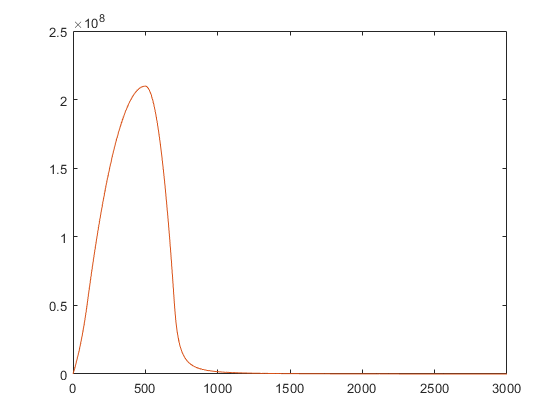

plot(XD,FD,XD,FDD)